# State feedback with integral action

Define model matrices

A = [0  1  0; 
     0 -1  1; 
     0  0 -5];
B = [0; 0; 5];
C = [1 0 0];
D = 0;

And assign the following set of eigenvalues

P = [-1-2*1i, -1+2*1i, -10, -30];

Define augmented state system

AA = [A zeros(3,1) ; -C 0]

AA =      0     1     0     0
     0    -1     1     0
     0     0    -5     0
    -1     0     0     0


BB = [B; 0]

BB =      0
     0
     5
     0


Verify controllability of the augmented system

Mr = ctrb(AA,BB)

Mr =      0     0     5   -30
     0     5   -30   155
     5   -25   125  -625
     0     0     0    -5


Mr = [BB AA*BB AA^2*BB AA^3*BB]

Mr =      0     0     5   -30
     0     5   -30   155
     5   -25   125  -625
     0     0     0    -5


rank(Mr)

ans = 4

Find the desired gain matrix

K = -place(AA,BB,P) % matlab assumes u = - Kx

K =  -160.0000  -68.8000   -7.2000  300.0000


Verify eigenvalues

eig(AA+BB*K)

ans =  -30.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i
 -10.0000 + 0.0000i


Check step response of the closed loop system

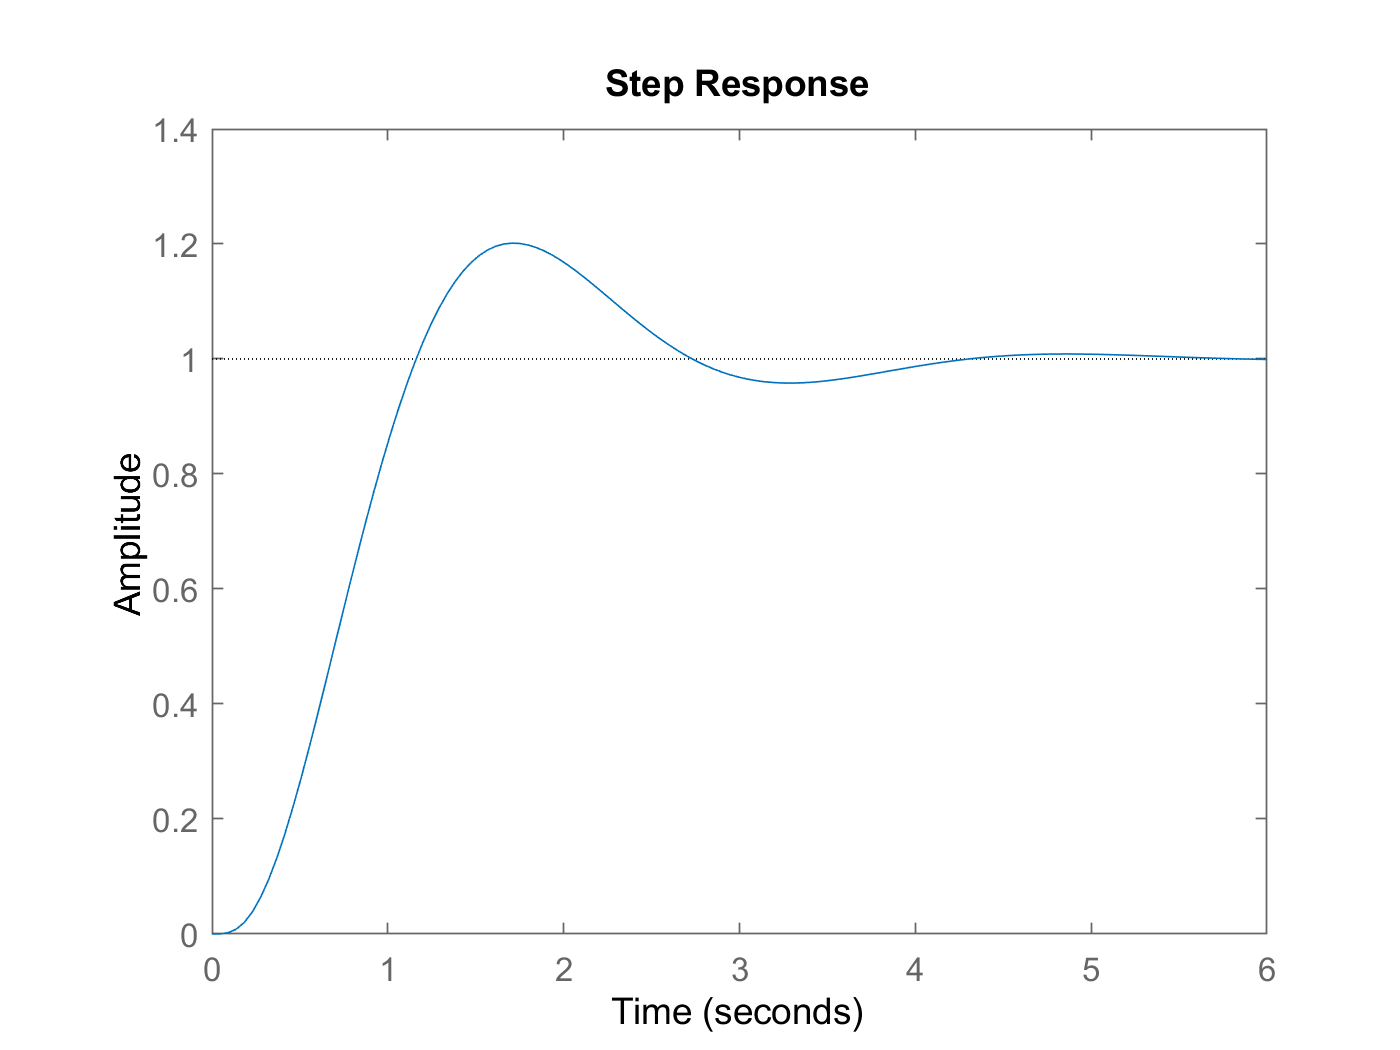

Acl = AA+BB*K;
Bcl = [0 0 0 1]'; % the input to the closed loop system is r(t)
Ccl = [1 0 0 0];
Dcl = 0;

clsys = ss(Acl,Bcl,Ccl,Dcl);
step(clsys)